# Soluciones analíticas sencillas

Separación de variables (variables separables)


$$\frac{\mathrm{d}}{\mathrm{d}t}y=k\;y$$
     
$$y\left(0\right)=3$$



$$\frac{\textrm{dy}}{y}=k\;\textrm{dt}$$
       
$$k=2$$


syms y(t) 
k = 2;
eqn = diff(y,t) == k*y

$$eqn(t) = \frac{\partial }{\partial t}y\left(t\right)=2\,y\left(t\right)$$

yG = dsolve(eqn)

$$yG = C_{3}\,{\mathrm{e}}^{2\,t}$$

cond = y(0) == 3

$$cond = y\left(0\right)=3$$

yP = dsolve(eqn,cond) % dsolve('Dy = 2*y, y(0)=3','t')

$$yP = 3\,{\mathrm{e}}^{2\,t}$$

yPs = simplify(yP)

$$yPs = 3\,{\mathrm{e}}^{2\,t}$$

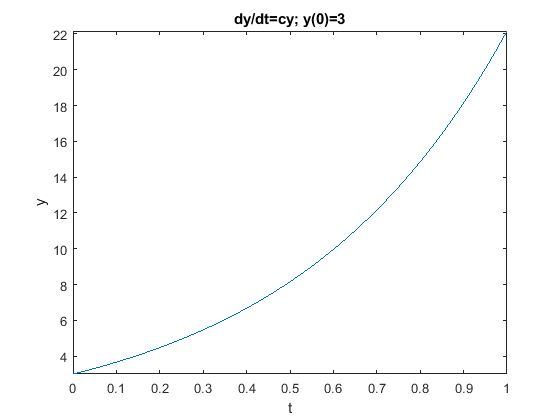

fplot(yPs, [0 1]);
title('dy/dt=cy; y(0)=3')
xlabel('t');
ylabel('y');

Separación de variables


$$y^{\prime } =-2t\;y$$
       
$$y\left(0\right)=4$$


%
syms y(t)
eqn = diff(y,t) == -2*t*y;
yG = dsolve(eqn);
yGs = simplify(yG);
cond = y(0) == 4;
yP = dsolve(eqn,cond);
yPs = simplify(yP)

$$yPs = 4\,{\mathrm{e}}^{-t^{2}}$$

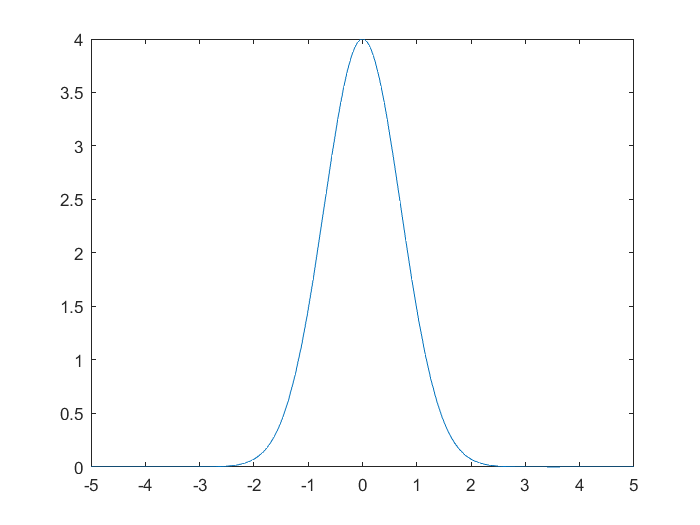

fplot(yPs);

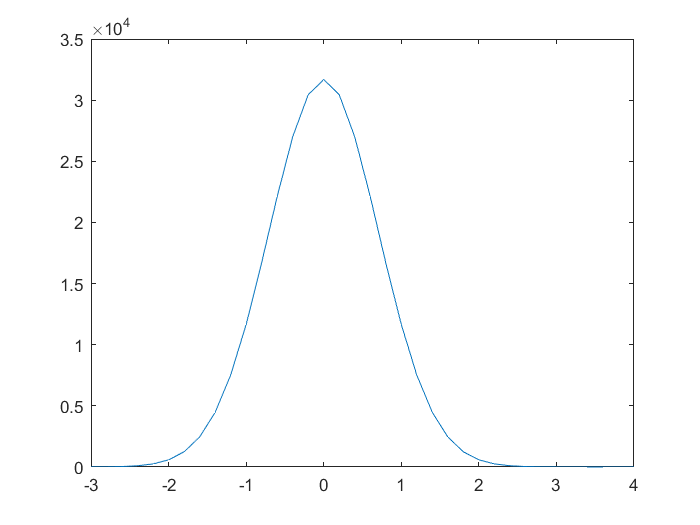

y0 = 4;
t0 = -3;
tf = 4;
h = 0.2;
f = @(t,y) -2*t*y;
[t,y] = odeRK4(f,y0,t0,tf,h);
plot(t,y)

Separación de variables


$$y^{\prime } =-y^2$$
      
$$y\left(1\right)=1$$


%
syms y(t)
eqn = diff(y,t) == -y^2;
cond = y(1) ==1;
yG = dsolve(eqn);
yGs = simplify(yG)

$$yGs = \left(\begin{array}{c} 0\\ -\frac{1}{C_{1}-t} \end{array}\right)$$

yP = dsolve(eqn,cond);
yPs = simplify(yP)

$$yPs = \frac{1}{t}$$

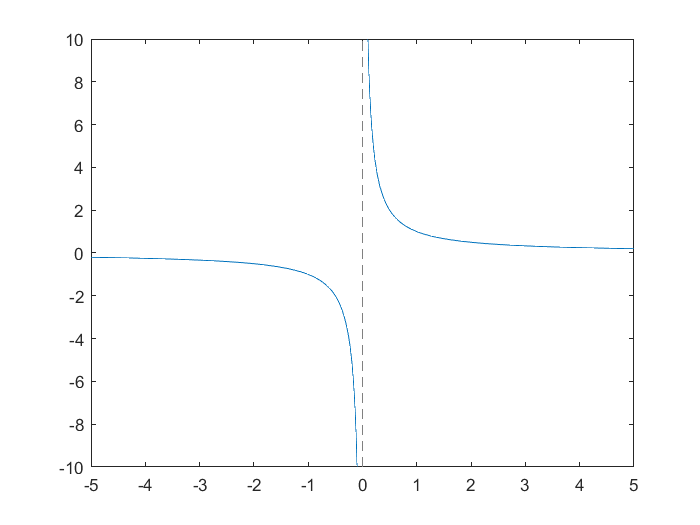

fplot(yPs)

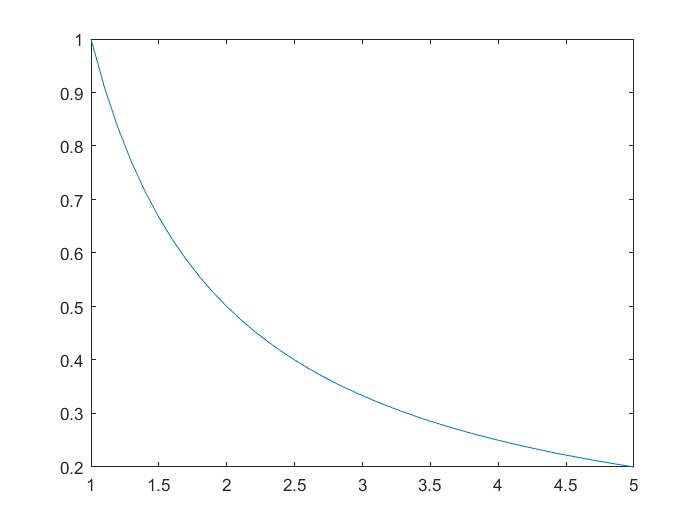

f = @(t,y) -y^2;
t0 = 1;
tf = 5;
y0 = 1;
h = 0.1;
[t,y] = odeRK4(f,y0,t0,tf,h);
plot(t,y)

Ecuación diferencial exacta


$$t\;y^{\prime } +y+4=0$$
         
$$y\left(1\right)=0$$


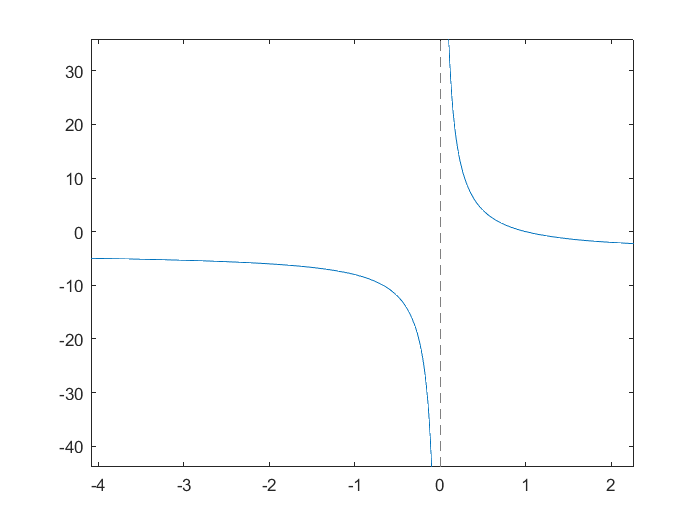

%
syms y(t)
eqn = diff(y,t) == (-y-4)/t;
yG = dsolve(eqn);
cond = y(1) == 0;
yP = dsolve(eqn,cond);
fplot(yP)

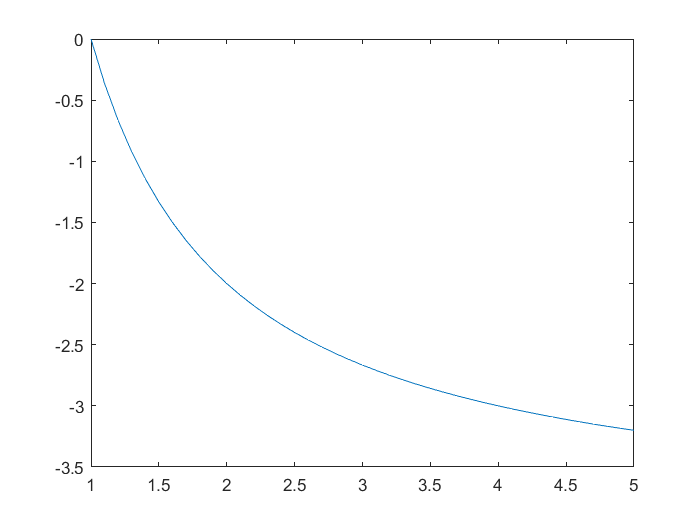


f = @(t,y) (-y-4)/t;
t0 = 1;
tf = 5;
y0 = 0;
h = 0.1;
[t,y] = odeRK4(f,y0,t0,tf,h);
plot(t,y)

Factor de integración


$$y^{\prime } =t\;y+t^3$$
       
$$y\left(0\right)=4$$


%

Factor de integración


$$y^{\prime } =-0\ldotp 5y+{4e}^{0\ldotp 8t}$$
       
$$y\left(0\right)=2$$


%

Caída libre con fricción

Lineal + Separación de variables

%

Small changes to an equation can complicate greatly the analytical solutions

y = dsolve('Dy = y^2')
y = dsolve('Dy = y^2-1')
y = dsolve('Dy = y^2+t')
y = dsolve('Dy = y^2+t^2')
y = dsolve('Dy = y^3+t^2')